N=51;
n=-(N-1)/2:(N-1)/2;
fc=1/6;
Fs=30000;

w=hamming (N)

w =     0.0800
    0.0836
    0.0945
    0.1123
    0.1369
    0.1679
    0.2047
    0.2468
    0.2935
    0.3441


h=-2*fc*sinc(n*2*fc)

h =    -0.0110    0.0000    0.0120    0.0125   -0.0000   -0.0138   -0.0145    0.0000    0.0162    0.0172   -0.0000   -0.0197   -0.0212    0.0000    0.0251    0.0276   -0.0000   -0.0345   -0.0394    0.0000    0.0551    0.0689   -0.0000   -0.1378   -0.2757   -0.3333   -0.2757   -0.1378   -0.0000    0.0689    0.0551    0.0000   -0.0394   -0.0345   -0.0000    0.0276    0.0251    0.0000   -0.0212   -0.0197   -0.0000    0.0172    0.0162    0.0000   -0.0145   -0.0138   -0.0000    0.0125    0.0120    0.0000


h((N-1)/2+1)=1-2*fc %"-(N-1)/2:(N-1)/2" 之间的零正好为"(N-1)/2+1"

h =    -0.0110    0.0000    0.0120    0.0125   -0.0000   -0.0138   -0.0145    0.0000    0.0162    0.0172   -0.0000   -0.0197   -0.0212    0.0000    0.0251    0.0276   -0.0000   -0.0345   -0.0394    0.0000    0.0551    0.0689   -0.0000   -0.1378   -0.2757    0.6667   -0.2757   -0.1378   -0.0000    0.0689    0.0551    0.0000   -0.0394   -0.0345   -0.0000    0.0276    0.0251    0.0000   -0.0212   -0.0197   -0.0000    0.0172    0.0162    0.0000   -0.0145   -0.0138   -0.0000    0.0125    0.0120    0.0000


ht=w.*h'

ht =    -0.0009
    0.0000
    0.0011
    0.0014
   -0.0000
   -0.0023
   -0.0030
    0.0000
    0.0048
    0.0059


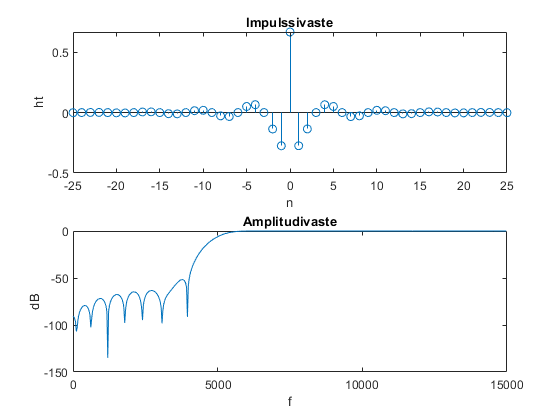


figure('name', 'suunniteltu ylipaastosuodin')

subplot(211)
stem(n,ht)
title('Impulssivaste')
xlabel('n') 
ylabel('ht') 

subplot(212)
[H,w]=freqz(ht);
plot(Fs*w/(2*pi),20*log10(abs(H)))%Fs*w/(2*pi=f
title('Amplitudivaste')
xlabel('f') 
ylabel('dB') 

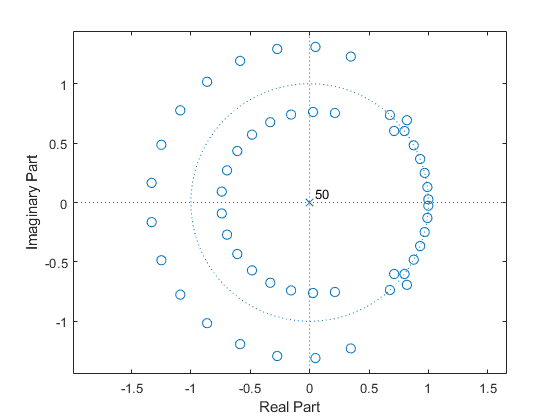


figure, zplane(ht')


%or
d=fir1(N-1,2*fc,'high',hamming(N))

d =    -0.0009   -0.0000    0.0011    0.0014   -0.0000   -0.0023   -0.0030   -0.0000    0.0048    0.0059    0.0000   -0.0089   -0.0108   -0.0000    0.0157    0.0188    0.0000   -0.0271   -0.0328   -0.0000    0.0502    0.0649    0.0000   -0.1357   -0.2744    0.6659   -0.2744   -0.1357    0.0000    0.0649    0.0502   -0.0000   -0.0328   -0.0271    0.0000    0.0188    0.0157   -0.0000   -0.0108   -0.0089    0.0000    0.0059    0.0048   -0.0000   -0.0030   -0.0023   -0.0000    0.0014    0.0011   -0.0000


figure,zplane(d)

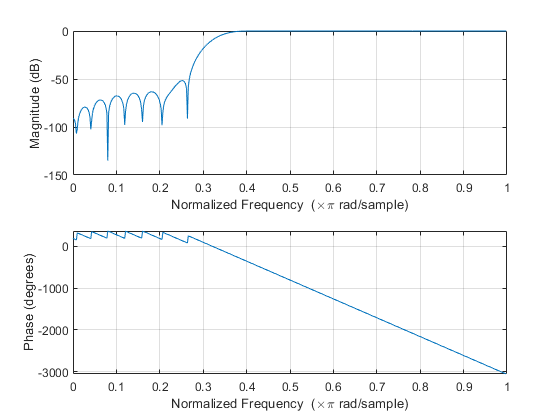

figure,freqz(d)